# ExportMlx User Guide

## Introduction

ExportMlx provides tools for converting Matlab Live Scripts to Markdown files. This is useful in generating rich documentation for Matlab programs.

The main function is `livescript2markdown`. There are also `livescript2latex` and `latex2markdown` functions for the individual steps of the process which give you finer-grained control over export options.

This User Guide itself is generated from a Live Script using ExportMlx!

## Installation and Setup

Download the project's distribution or clone the repo and put it somewhere on your disk.

Add its `Mcode` directory to your Matlab path using Matlab's `addpath()` function.

## Usage: Simple

All the code lives in the `janklab.exportmlx` package.

Call `livescript2markdown(mlxFile)` on your `.mlx` Live Script file to export it to Markdown.

## Usage: Advanced

### Step 1: Export your Live Script to LaTeX using `livescript2latex`

This will generate `README.tex`. All the related images, such as included images and generated figures, are saved under the folder `README_images` next to the `.tex` file.

**WARNING**: When exporting to LaTeX right after running the Live Script, it's observed that the figures will be exported as EPS files or not at all if the Live Script contains more than 20 figures. I suggest that **you close the script, reopen it, and then export to LaTeX.**

### Step 2: Convert the LaTeX to Markdown using `latex2markdown`

This will generate `README.md`, a Markdown file suitable for GitHub.

The `latex2markdown` function supports the following options:

- `'format'`: Style of Markdown to generate. May be `'github'` (default) or `'qiita'` 

- `'outputfilename'`: The name of the Markdown file to be generated. If unspecified, will be the same as the Live Script, but with an `.md` file extension.

- `'png2jpeg'`: Convert PNG images to JPEG images to save space at the expense of image quality. May be `false` (default) or `true`.

See the helptext and source code for `latex2markdown` for more details.

Example: A Markdown file suitable for Qiita, named `QiitaDraft.md`, will be generated by the following command:

Note: Qiita is a tech blog platform in Japanese. Qiita uses Markdown for its posts.

## Differences Between Qiita and GitHub Formats

One is the equations and the other is how to insert the image files. 

Qiita allows you to use LaTeX to represent equations (like GitLab?) whereas GitHub does not. For GitHub, ExportMlx uses CODECOGS ([https://latex.codecogs.com](https://latex.codecogs.com)) to render the equations as images. 

Rendering equations with CODECOGS is done by sticking CODECOGS query URLs in image references in the Markdown. The image files are fetched from codecogs at document viewing time; they are not stored locally. This may not be suitable for all use cases.

For images, you can just push the image folders and then the README reads them, but you need to drag & drop your images inside the Qiita Editor.

## Supported Syntax in Live Scripts

### MATLAB Code

MATLAB code and its output and figures will be shown as follows:

% Matlab code
x = linspace(0,2*pi,100);
y = sin(x)

y =          0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638    0.9450    0.9224    0.8960    0.8660    0.8326    0.7958    0.7557    0.7127    0.6668    0.6182    0.5671    0.5137    0.4582    0.4009    0.3420    0.2817    0.2203    0.1580    0.0951    0.0317


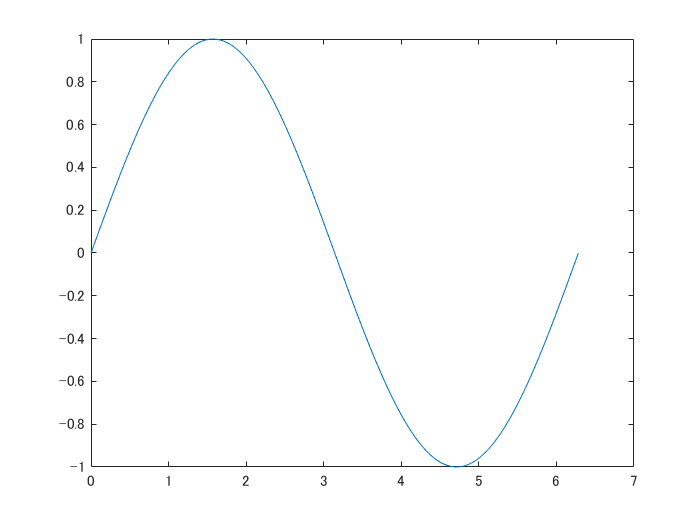

% Figures
plot(x,y);

### Table display

The display of `table` arrays will be formated like so:

array2table(rand(3,4))

ans = 3×4 table
     Var1       Var2       Var3       Var4  
    _______    _______    _______    _______

    0.69908    0.54722    0.25751    0.81428
     0.8909    0.13862    0.84072    0.24352
    0.95929    0.14929    0.25428    0.92926


BUG: If the table contains multicolumn variables, the format is not perfect. Column headings will not be placed correctly.

table(rand(3,4))

ans = 3×1 table
                      Var1                  
    ________________________________________

    0.34998    0.61604    0.83083    0.91719
     0.1966    0.47329    0.58526    0.28584
    0.25108    0.35166    0.54972     0.7572


(Any suggestions to handle merged cells in Markdown are appreciated!)

### Code Examples

"MATLAB" Code Examples (as opposed to actual executable Matlab code) are rendered as follows:

"Plain" Code Examples look like this:

### Inline Images

Here's a display of an inline image (an image pasted into the Live Script, as opposed to figure display output).

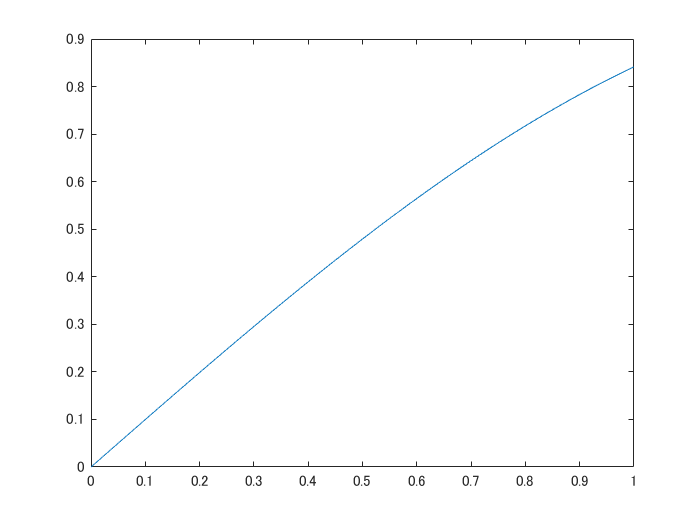

### Equations

Any equations in Live Scripts will be exported as LaTeX. For GitHub, CODECOGS helps display them by rendering them as images at document viewing time.

Here's an inline equation: $\sin^2 x + \cos^2 x = 1$. 

If you have multiple lines of equations:


$$\sin x = - \int \cos{x} dx \\
\cos x = \int \sin{x} dx

$$


Single line equations look like this:


$$\sin x = - \int \cos{x} dx$$


### Lists

Here's a unordered list:

- Item foo

- Item bar

- Item baz

Here's an ordered list:

- Item one

- Item two

- Item three

### Font Styles

Here are the complete list of font styles available in Live Editor:

- **Bold**

- *Italic*

- Underline

- `Monospace`.

And some conbinations of styles:

- ***BoldItalic***

- **BoldUnderline**

- `BoldMonospace`

- *ItalicUnderline*

- `ItalicMonospace`

- `UnderlineMonospace`

- ***BoldItalicUnderline***

- `BoldItalicMonospace`

- `BoldUnderlineMonospace`

- `ItalicUnderlineMonospace`

Note that underlines do not show up in the Markdown! (I think this is because Markdown doesn't have markup for underlines?)

### Quotations

There's not a corresponding function, but centered paragraphs are treated as quotations.

There's not a corresponding function, but this centered paragraph is treated as quotation.

## Feedback and Support

Hope this accelerates your Matlab life! Any comments and suggestions are welcome. Visit the project repo at [https://github.com/janklab/ExportMlx](https://github.com/janklab/ExportMlx).